clc; clear;
dsFolder = "p_dataset_26";
subFolder = ["0", "4", "7", "8", "A", "D", "H"];
categories = ["0", "4", "7", "8", "A", "D", "H"];

allData = table('Size', [0, 2], 'VariableTypes', {'cell', 'cell'}, 'VariableNames', {'Image', 'Label'});

desiredSize = [224, 224]; % Set your desired image size

for i = 1:length(subFolder)
    folderPath = fullfile(dsFolder, subFolder(i));
    pngFiles = dir(fullfile(folderPath, "*.png"));

    for j = 1:length(pngFiles)
        pngFilePath = fullfile(folderPath, pngFiles(j).name);
        image = imread(pngFilePath);
        
        % Resize or pad the image to the desired size
        % resizedImage = imresize(image, desiredSize);
        % Alternatively, use padarray to add padding
        % paddedImage = padarray(image, [desiredSize(1)-size(image,1), desiredSize(2)-size(image,2)], 0, 'post');
        
        % Store the resized/padded image and label
        allData = [allData; {image, categories(i)}];
        
%         allData = [allData; {image, categories(i)}];
    end
end

% define images & labels
numImages = size(allData, 1);
imageSize = size(allData.Image{1});
images = zeros(imageSize(1), imageSize(2), 1, numImages);

for i = 1:numImages
    images(:, :, 1, i) = allData.Image{i};
end

labels = categorical(allData.Label);

% split data into train and test set
cv = cvpartition(labels, 'HoldOut', 0.25);
trainIdx = training(cv);
testIdx = test(cv);
trainImages = images(:, :, :, trainIdx);
trainLabels = labels(trainIdx);
testImages = images(:, :, :, testIdx);
testLabels = labels(testIdx);

% Define the layers of the CNN
layers = [
    imageInputLayer([imageSize 1])

    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    fullyConnectedLayer(numel(categories))
    softmaxLayer
    classificationLayer
    ];

% Training options
options = trainingOptions( ...
    'sgdm', ... % Stochastic Gradient Descent with Momentum
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {testImages, testLabels}, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        7.81% |       36.04% |       2.9280 |       5.8415 |          0.0100 |
|       3 |          30 |       00:00:18 |       85.16% |       88.06% |       0.4829 |       0.3420 |          0.0100 |
|       5 |          50 |       00:00:28 |       92.97% |              |       0.2272 |              |          0.0100 |
|       6 |          60 |       00:00:33 |       96.09% |       92.34% |       0.1543 |   

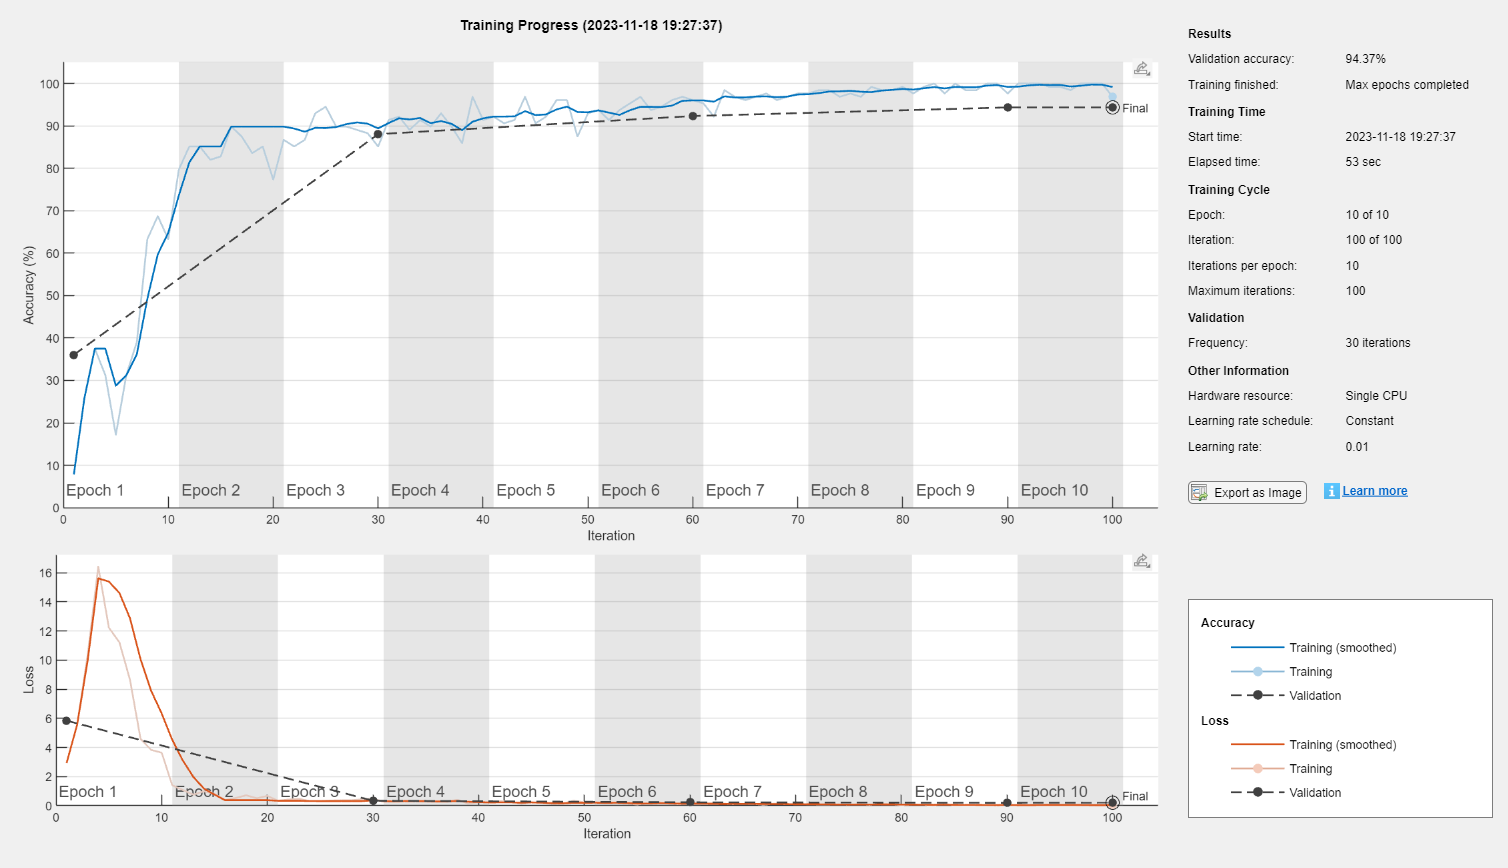

% Train the CNN

trainingStartTime = tic;

% Train the neural network
net = trainNetwork(trainImages, trainLabels, layers, options);


% Stop the timer
trainingTime = toc(trainingStartTime);

% Display the training time
fprintf('Training time: %.2f seconds\n', trainingTime);

Training time: 58.10 seconds



% save CNN model
save('trainedCNN.mat', 'net');

% Classify Test Images
predictedLabels = classify(net, testImages);

% Calculate the Accuracy
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test Accuracy: %.2f%%\n', accuracy * 100);

% Calculate precision, recall, and F1-score
confusionMatrix = confusionmat(testLabels, predictedLabels)

truePositive = confusionMatrix(1, 1);
falsePositive = confusionMatrix(2, 1);
falseNegative = confusionMatrix(1, 2);

precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f\n', precision);
fprintf('Recall: %.2f\n', recall);
fprintf('F1-Score: %.2f\n', f1Score);
% Visualize the confusion matrix using imagesc and annotate precision
figure;
imagesc(confusionMatrix);
colorbar;
colormap('jet'); % You can change the colormap as needed
title('Confusion Matrix');
xlabel('Predicted');
ylabel('Actual');
xticks(1:numel(categories));
xticklabels(categories);
yticks(1:numel(categories));
yticklabels(categories);

% Calculate and annotate precision for each class
for i = 1:numel(categories)
    for j = 1:numel(categories)
        precision = confusionMatrix(i, i) / sum(confusionMatrix(:, i));
       text(j, i, sprintf('%.2f', precision), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'k', 'FontWeight', 'bold');
    end
end

% Hyperparameter tuning for the number of epochs
numEpochsList = [5, 10, 15, 20]; % You can modify this list according to your requirements

% Initialize a matrix to store accuracy for each number of epochs
EpochsAccuracyMatrix = zeros(length(numEpochsList), 1);
% Initialize a matrix to store training for each number of epochs
EpochsTime = zeros(length(numEpochsList), 1);

for idx = 1:length(numEpochsList)
    currentNumEpochs = numEpochsList(idx);

    % Update the MaxEpochs parameter in trainingOptions
    options.MaxEpochs = currentNumEpochs;
    
    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    EpochsAccuracyMatrix(idx) = accuracy;
    EpochsTime(idx) = trainingTime;

    fprintf('Test Accuracy for %d Epochs: %.2f%%\n', currentNumEpochs, accuracy * 100);
end


% Plot the accuracy performance
figure;

bar(numEpochsList, EpochsAccuracyMatrix);

ylim([0.9, 1]); 
xlabel('Number of Epochs');
ylabel('Accuracy');
title('Accuracy Performance vs Number of Epochs');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/epochs.eps'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);

% Plot the training time
figure;

bar(numEpochsList, EpochsTime);

xlabel('Number of Epochs');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Number of Epochs');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/epochs_trainingtime.eps'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);

% Hyperparameter tuning for the number of learning rates
learningRates = [0.01, 0.001, 0.0001]; % You can modify this list according to your requirements

% Initialize a matrix to store accuracy for each number of epochs
LRaccuracyMatrix = zeros(length(learningRates), 1);
LRTrainingTime = zeros(length(learningRates), 1);

for idx = 1:length(learningRates)
    currentlearningRate = learningRates(idx);

    % Update the MaxEpochs parameter in trainingOptions
    options.InitialLearnRate = currentlearningRate;
    options.MaxEpochs = 15;

    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    LRaccuracyMatrix(idx) = accuracy;
    LRTrainingTime(idx) = trainingTime;

    fprintf('Test Accuracy for %d Learning Rate: %.2f%%\n', currentlearningRate, accuracy * 100);
end

% Plot the accuracy performance
learningRates = {'0.01', '0.001','0.0001'};
learningRateValues = [1, 2, 3];
figure;

% bar(learningRates, LRaccuracyMatrix);
bar(learningRateValues, LRaccuracyMatrix);
xticks(learningRateValues);
xticklabels(learningRates);

xlabel('Learning Rates');
ylabel('Accuracy');
ylim([0.9, 1]); 

title('Accuracy Performance vs Learning Rates');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/learning_rate_accuracy.eps'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);

% Plot the accuracy performance
learningRates = {'0.01', '0.001','0.0001'};
learningRateValues = [1, 2, 3];
figure;

% bar(learningRates, LRaccuracyMatrix);
bar(learningRateValues, LRTrainingTime);
xticks(learningRateValues);
xticklabels(learningRates);

xlabel('Learning Rates');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Learning Rates');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/learning_rate_trainingtime.eps'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);

% Hyperparameter tuning for the number of epochs
optimizers = {'sgdm', 'adam', 'rmsprop'}; % You can modify this list according to your requirements

% Initialize a matrix to store accuracy for each number of epochs
OaccuracyMatrix = zeros(length(optimizers), 1);
OTrainingTime = zeros(length(optimizers), 1);

for idx = 1:length(optimizers)
    currentoptimizer = optimizers(idx);

    options = trainingOptions( ...
    currentoptimizer, ... % Stochastic Gradient Descent with Momentum
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 15, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {testImages, testLabels}, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

    % Update the MaxEpochs parameter in trainingOptions
    % options.InitialLearnRate = currentlearningRate;
    % options.MaxEpochs = 15;
    % options.InitialLearnRate = 0.01;

    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    OaccuracyMatrix(idx) = accuracy;
    OTrainingTime(idx) = trainingTime;

    % fprintf('Test Accuracy for %s Learning Rate: %.2f%%\n', currentoptimizer, accuracy * 100);
end

% Plot the accuracy performance
figure;
bar(optimizers, OaccuracyMatrix);
xlabel('Optimizers');
ylabel('Accuracy');
ylim([0.9, 1]); 
title('Accuracy Performance vs Optimizers');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/optimiser.eps'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);

% Plot the training time
figure;

bar(optimizers, OTrainingTime);

xlabel('Optimizers');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Optimizers');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/optimiser_trainingtime.eps'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);


% Hyperparameter tuning for the number of epochs
batch_size = [8,16,32]; % You can modify this list according to your requirements

% Initialize a matrix to store accuracy for each number of epochs
batchaccuracyMatrix = zeros(length(batch_size), 1);
batchTrainingTime = zeros(length(batch_size), 1);

for idx = 1:length(batch_size)
    currentbatch_size = batch_size(idx);

    options = trainingOptions( ...
    'sgdm', ... % Stochastic Gradient Descent with Momentum
    'MiniBatchSize', currentbatch_size, ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 15, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {testImages, testLabels}, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

    % Update the MaxEpochs parameter in trainingOptions
    % options.InitialLearnRate = currentlearningRate;
    % options.MaxEpochs = 15;
    % options.InitialLearnRate = 0.01;

    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    batchaccuracyMatrix(idx) = accuracy;
    batchTrainingTime(idx) = trainingTime;

    % fprintf('Test Accuracy for %s Learning Rate: %.2f%%\n', currentoptimizer, accuracy * 100);
end

% Plot the accuracy performance
batch_size = [8,16,32];
figure;
bar(batch_size, batchaccuracyMatrix);
xlabel('Batch Size');
ylabel('Accuracy');
ylim([0.9, 1]); 
title('Accuracy Performance vs Batch Size');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/batchsize.eps';
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);

% Plot the training time
figure;
bar(batch_size, batchTrainingTime);

xlabel('Batch Size');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Batch Size');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/batch_size_trainingtime.eps'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);

% Constants
numConvLayersList = [2, 3, 4]; % Vary the number of convolution layers
numConfigs = numel(numConvLayersList);
LayersaccuracyResults = zeros(numConfigs, 1);
LayersTrainingTime = zeros(numConfigs, 1);

% Loop through different configurations
for i = 1:numConfigs
    % Define the neural network architecture with varying convolution layers
    layers = [
        imageInputLayer([imageSize 1])
    ];
    
    for j = 1:numConvLayersList(i)
        layers = [layers
            convolution2dLayer(3, 16, 'Padding', 'same')
            batchNormalizationLayer
            reluLayer
            maxPooling2dLayer(2, 'Stride', 2)
        ];
    end
    
    layers = [layers
        fullyConnectedLayer(numel(categories))
        softmaxLayer
        classificationLayer
    ];

    % Set training options
    options = trainingOptions( ...
        'sgdm', ... % Stochastic Gradient Descent with Momentum
        'InitialLearnRate', 0.01, ...
        'MaxEpochs', 10, ...
        'Shuffle', 'every-epoch', ...
        'ValidationData', {testImages, testLabels}, ...
        'ValidationFrequency', 30, ...
        'Verbose', true, ...
        'Plots', 'training-progress' ...
        );

    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    
    % Store the accuracy for this configuration
    LayersaccuracyResults(i) = accuracy;
    LayersTrainingTime(i) = trainingTime;
end


% Plot the results
figure;
bar(numConvLayersList, LayersaccuracyResults)
xlabel('Number of Convolution Layers')
ylabel('Accuracy')
ylim([0.9, 1]); 
title('Accuracy Performance vs Number of Convolution Layers')
grid on;

% Save the plot as an EPS file
eps_filename = 'results/layers.eps'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);

% Plot the training time
figure;
bar(numConvLayersList, LayersTrainingTime);

xlabel('Number of Convolution Layers');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Number of Convolution Layers');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/layers_trainingtime.eps'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);